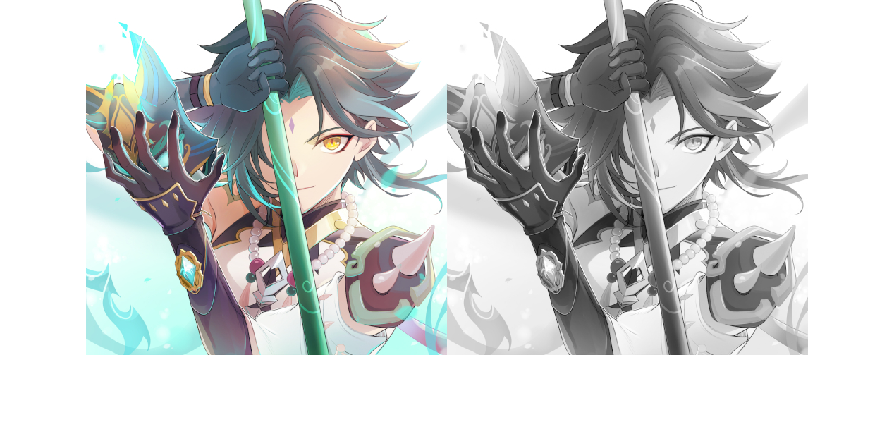

im = imread("yaksha.jpg");
I = rgb2gray(im);
imshowpair(im, I, "montage");

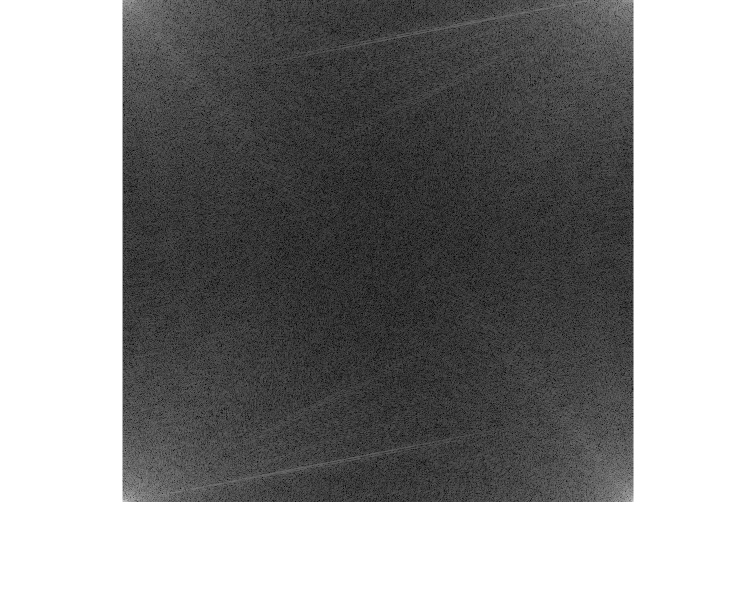

F = fft2(I);
imshow(log(abs(F)+1), [])

imwrite(mat2gray(log(abs(F)+1)), "exp6/fft.jpg")

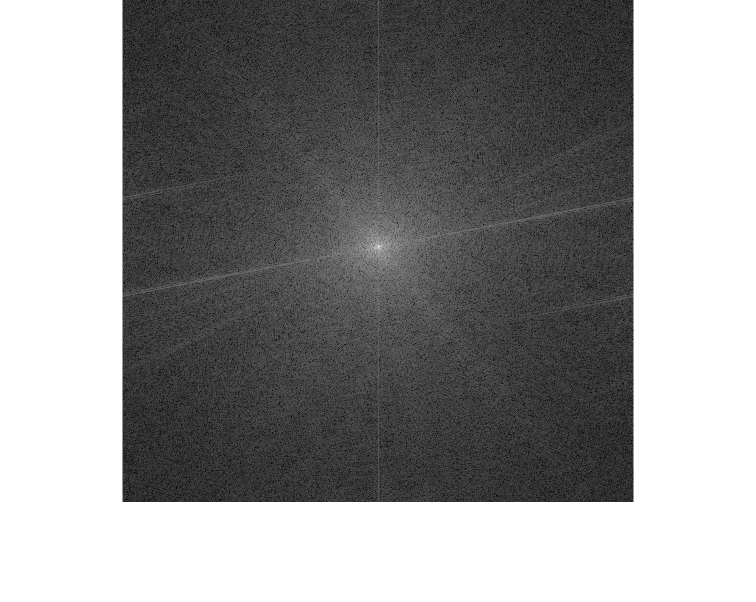

F1 = fftshift(F);
G = log(abs(F1)+1);
imshow(G, [])

imwrite(mat2gray(G), "exp6/ffts.jpg")

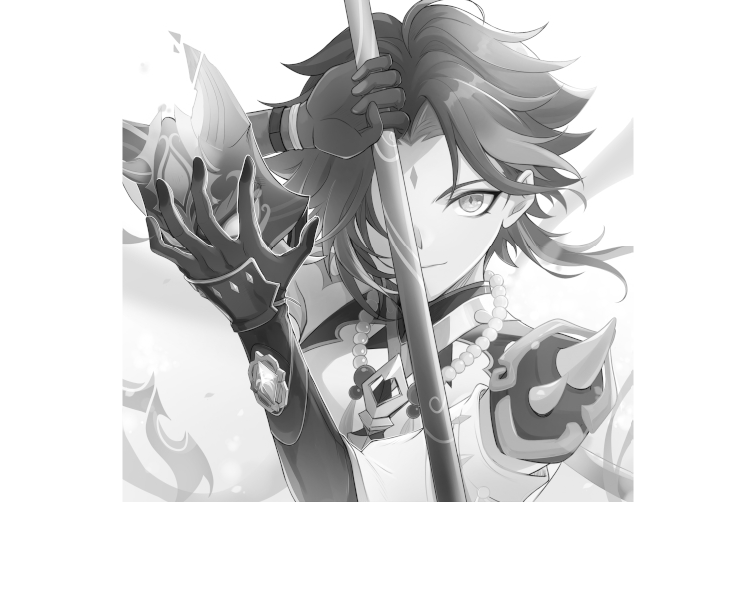

G2 = ifftshift(F1);
imwrite(G2, "exp6/iffts.jpg")
I = uint8(ifft2(G2));
imshow(I)

imwrite(I, "exp6/ifft.jpg")

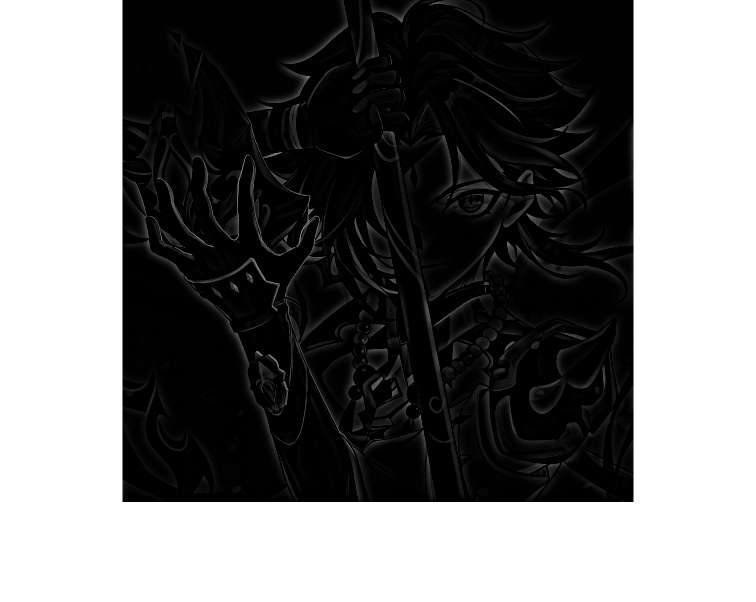

imh = filter(F1, 20, "high");
imshow(imh)

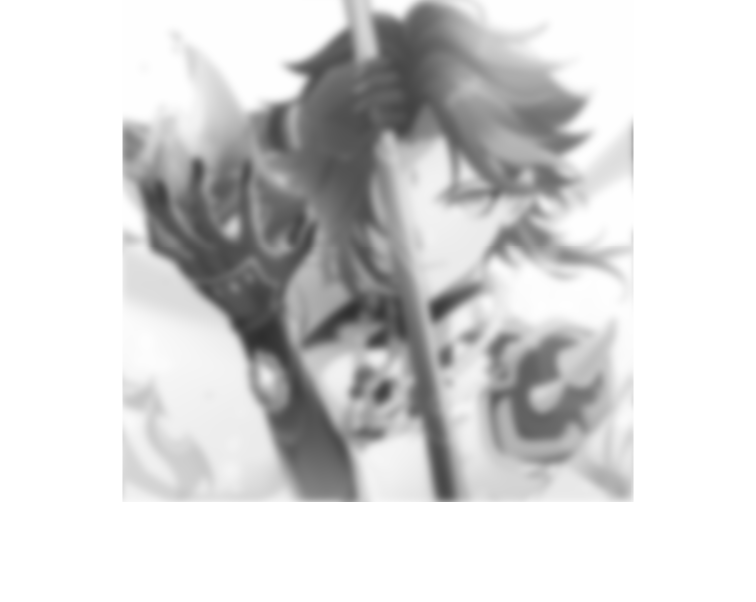

imwrite(imh, "exp6/high.jpg")
iml = filter(F1, 20, "low");
imshow(iml)

imwrite(iml, "exp6/low.jpg")

I = im2double(I);
imshow(I)

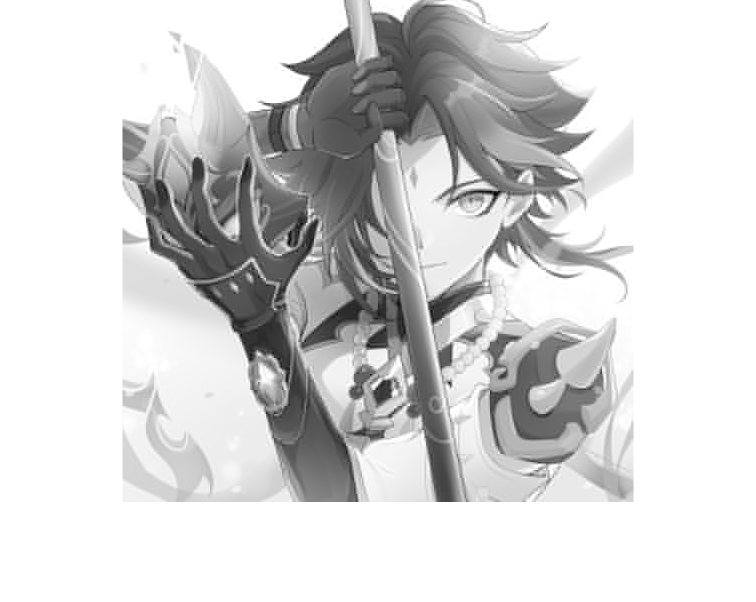

imwrite(I, "exp6/pdct.jpg")
T = dctmtx(8);
dct = @(block_struct) T * block_struct.data * T';
B = blockproc(I,[8 8],dct);
imwrite(B, "exp6/dct.jpg")
mask = [1   1   1   1   0   0   0   0
        1   1   1   0   0   0   0   0
        1   1   0   0   0   0   0   0
        1   0   0   0   0   0   0   0
        0   0   0   0   0   0   0   0
        0   0   0   0   0   0   0   0
        0   0   0   0   0   0   0   0
        0   0   0   0   0   0   0   0];
B2 = blockproc(B,[8 8],@(block_struct) mask .* block_struct.data);
imwrite(B2, "exp6/comp.jpg")
invdct = @(block_struct) T' * block_struct.data * T;
I2 = blockproc(B2,[8 8],invdct);
imshow(I2)

imwrite(I2, "exp6/podct.jpg")

function imh = filter(F1, d0, mode)
    [H, W] = size(F1);
    i = repmat((1 : H)', 1, W);
    j = repmat(1 : W, H, 1);
    
    d = sqrt((i - fix(H / 2)) .^ 2 + (j - fix(W / 2)) .^ 2);
    h = exp(-d .* d / (2 * d0 * d0));
    
    if mode == "high"
        h = 1 - h;
    end
    
    F = h .* F1;
    imh = ifftshift(F);
    imh = ifft2(imh);
    imh = uint8(real(imh));
end